Find all images in data and store them in source.mat in vector forms

%create x and y values
x = zeros(1,50*50,3);
y = [];

Air Section:

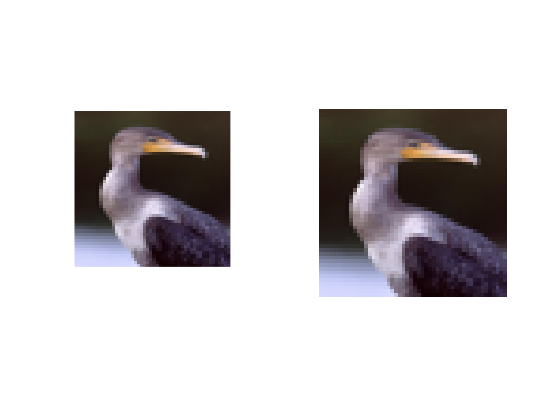

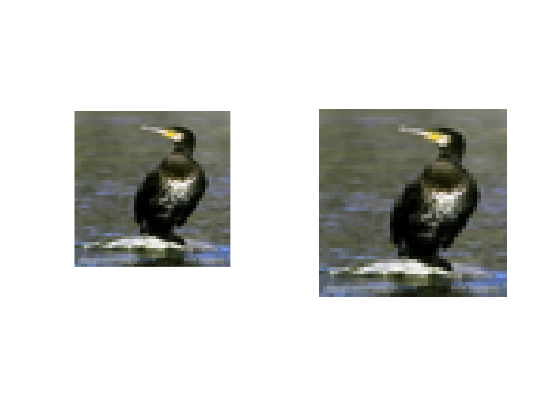

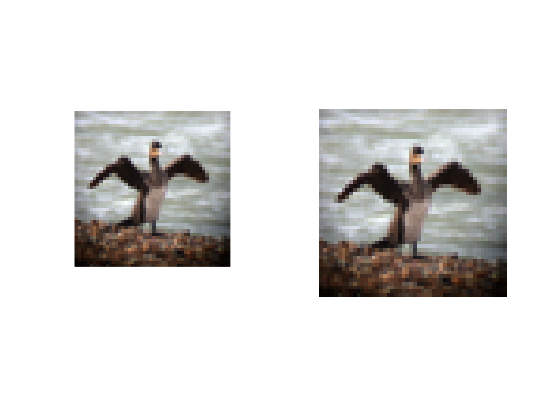

%check air folder exists
myFolder = 'Data/Air';
if ~isdir(myFolder)
    errorMessage = sprintf('Error : the following folder does not exist:\n%s',myFolder);
    wuwait(warndlg(errorMessage));
    return;
end
%get a list of all files in the folder
filePattern = fullfile(myFolder,'*.jpg');%Find all pictures
theFiles = dir(filePattern);%get list of all pitures matching pattern
for k = 1 : length(theFiles) %loop through all images
    baseFileName = theFiles(k).name; % target files name
    fullFileName = fullfile(myFolder,baseFileName); %gets the long address of file
    imageArray = imread(fullFileName);
    croppedImage = imresize(imageArray,[50,50]);
    figure();
    subplot(1,2,1)
    hold on;
    imshow(croppedImage);% display image
    [rows,~] = size(x(:,:,i)); %get the current row length
    
    for i = 1:3 %store this image in rows of RGB
        imageColour = croppedImage(:,:,i);%grab one colour to store in x
        x(rows+1,:,i) = reshape(imageColour,1,50*50);%reshape colour to be in row vector
    end
    %show that we can rebuild image using x
    subplot(1,2,2);
    %convert the values in x into uint8 for display
    remakeImage = uint8(reshape(x(rows+1,:,:),[50 50 3]));
    imshow(remakeImage)
    y(end+1,1) = 1;
end

Now we do this for the whole of Land and water

Land section :

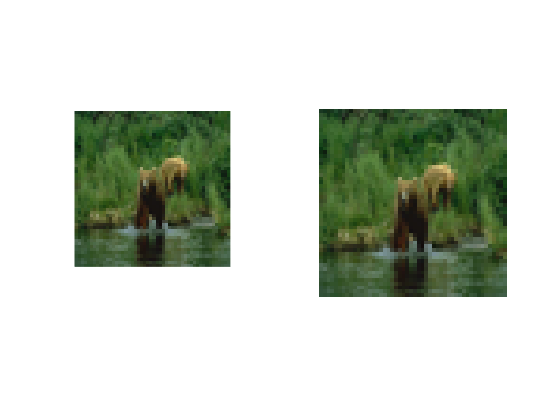

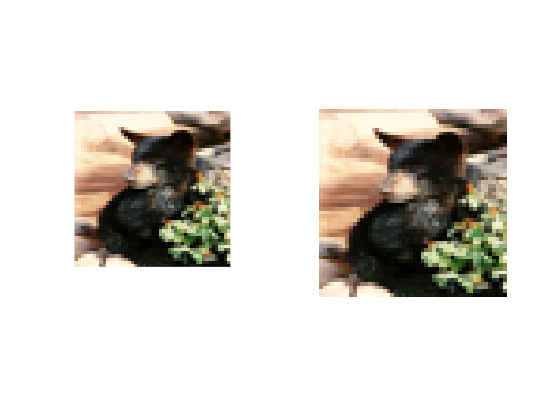

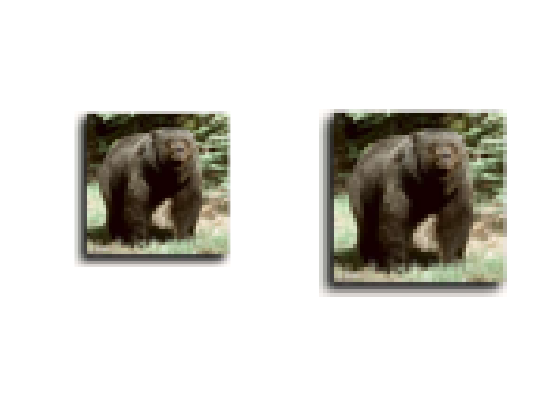

%check air folder exists
myFolder = 'Data/Land';
if ~isdir(myFolder)
    errorMessage = sprintf('Error : the following folder does not exist:\n%s',myFolder);
    wuwait(warndlg(errorMessage));
    return;
end
%get a list of all files in the folder
filePattern = fullfile(myFolder,'*.jpg');%Find all pictures
theFiles = dir(filePattern);%get list of all pitures matching pattern
for k = 1 : length(theFiles) %loop through all images
    baseFileName = theFiles(k).name; % target files name
    fullFileName = fullfile(myFolder,baseFileName); %gets the long address of file
    imageArray = imread(fullFileName);
    croppedImage = imresize(imageArray,[50,50]);
    figure();
    subplot(1,2,1)
    hold on;
    imshow(croppedImage);% display image
    [rows,~] = size(x(:,:,i)); %get the current row length
    for i = 1:3 %store this image in rows of RGB
        imageColour = croppedImage(:,:,i);%grab one colour to store in x
        x(rows+1,:,i) = reshape(imageColour,1,50*50);%reshape colour to be in row vector
    end
    %show that we can rebuild image using x
    subplot(1,2,2)
    %convert the values in x into uint8 for display
    remakeImage = uint8(reshape(x(rows+1,:,:),[50 50 3]));
    imshow(remakeImage)
    y(end+1,1) = 2;
end

Now for the Water Section:

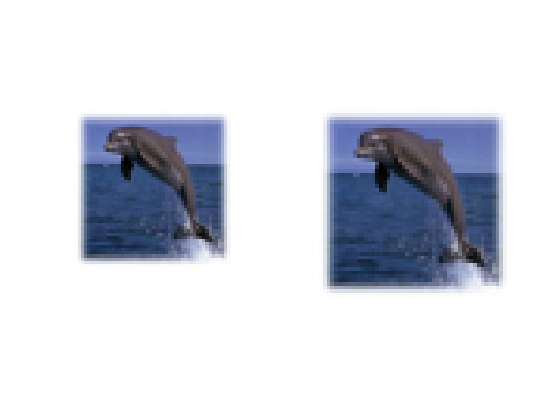

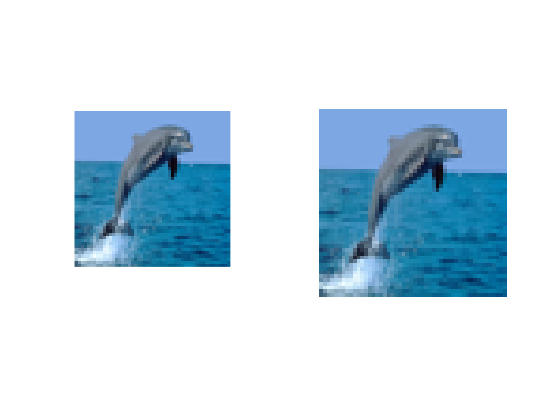

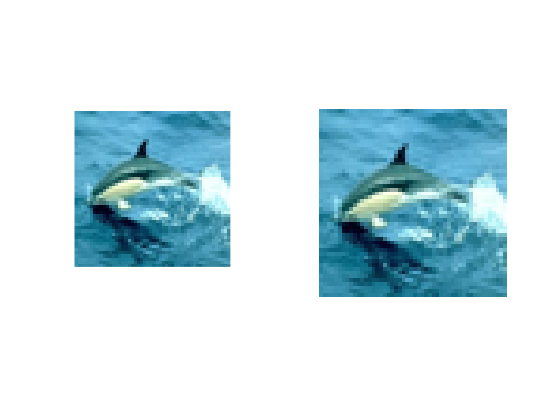

%check air folder exists
myFolder = 'Data/Water';
if ~isdir(myFolder)
    errorMessage = sprintf('Error : the following folder does not exist:\n%s',myFolder);
    wuwait(warndlg(errorMessage));
    return;
end
%get a list of all files in the folder
filePattern = fullfile(myFolder,'*.jpg');%Find all pictures
theFiles = dir(filePattern);%get list of all pitures matching pattern
for k = 1 : length(theFiles) %loop through all images
    baseFileName = theFiles(k).name; % target files name
    fullFileName = fullfile(myFolder,baseFileName); %gets the long address of file
    imageArray = imread(fullFileName);
    croppedImage = imresize(imageArray,[50,50]);
    figure();
    subplot(1,2,1)
    hold on;
    imshow(croppedImage);% display image
    [rows,~] = size(x(:,:,i)); %get the current row length
    for i = 1:3 %store this image in rows of RGB
        imageColour = croppedImage(:,:,i);%grab one colour to store in x
        x(rows+1,:,i) = reshape(imageColour,1,50*50);%reshape colour to be in row vector
    end
    %show that we can rebuild image using x
    subplot(1,2,2)
    %convert the values in x into uint8 for display
    remakeImage = uint8(reshape(x(rows+1,:,:),[50 50 3]));
    imshow(remakeImage)
    y(end+1,1) = 3;
end

Now we need to remove the first entry as its empty by design

x = x(2:end,:,:);

Now our y labels and x data match up

Now we store these x values of images and the y labels in a structure

data.X = x;
data.Y = y;
save('Data.mat','data');